
% Define symbolic variables with meaningful names
syms C V D v m rho Cp K n  % Using Unicode where possible

% Define the symbolic terms
Ree = (V * D / v)^m        % First term: (Velocity * L / KinematicViscosity)^m

$$Ree = {\left(\frac{\text{D}\,V}{v}\right)}^{m}$$

Pre = (v * rho * Cp / K)^n   % Second term: (KinematicViscosity * Density * HeatCap / Conductivity)^n

$$Pre = {\left(\frac{\mathrm{Cp}\,\rho \,v}{K}\right)}^{n}$$


simplified = C* V^m * D^m * v^(n-m) * rho^n * Cp^n * K^(-n)

$$simplified = \frac{C\,{\mathrm{Cp}}^{n}\,{\text{D}}^{m}\,V^{m}\,\rho^{n}\,v^{n-m}}{K^{n}}$$

lk = simplified* D * K

$$lk = \frac{C\,{\mathrm{Cp}}^{n}\,\text{D}\,{\text{D}}^{m}\,K\,V^{m}\,\rho^{n}\,v^{n-m}}{K^{n}}$$

% Compute simplified symbolic expression
lk

$$lk = \frac{C\,{\mathrm{Cp}}^{n}\,\text{D}\,{\text{D}}^{m}\,K\,V^{m}\,\rho^{n}\,v^{n-m}}{K^{n}}$$

simplifiedExpr3 = simplify(lk)

$$simplifiedExpr3 = C\,{\mathrm{Cp}}^{n}\,{\text{D}}^{m+1}\,K^{1-n}\,V^{m}\,\rho^{n}\,v^{n-m}$$

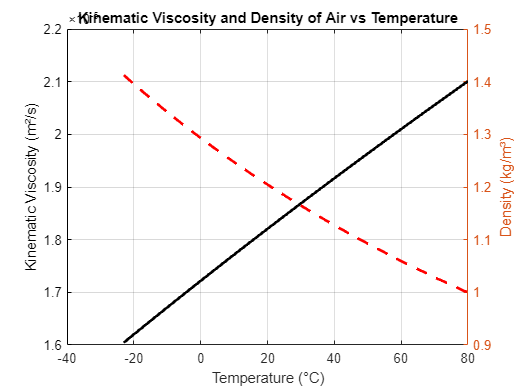



% Define the temperature range in Kelvin
T = 273.15 + (-23:80);  % Temperature from 0°C to 100°C

% Calculate kinematic viscosity for air at each temperature
v = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('V', 'T', temp, 'P', 101325, 'Air'), T);
rho = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('D', 'T', temp, 'P', 101325, 'Air'), T);

% Plotting kinematic viscosity vs temperature
figure;
plot(T - 273.15, v, 'k-', 'LineWidth', 2);  % Temperature in °C
xlabel('Temperature (°C)');
ylabel('Kinematic Viscosity (m²/s)');
title('Kinematic Viscosity and Density of Air vs Temperature');
grid on;

% Right y-axis: Density
yyaxis right;
plot(T - 273.15, rho, 'r--', 'LineWidth', 2);  % Temperature in °C
ylabel('Density (kg/m³)');

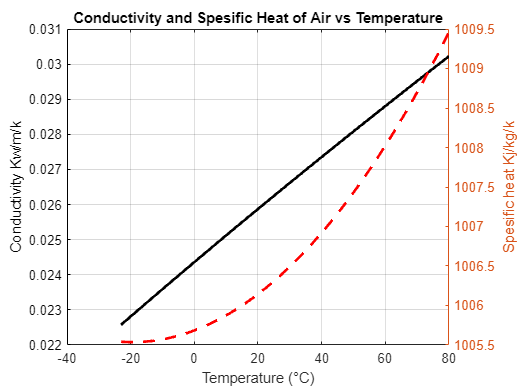



% Calculate kinematic viscosity for air at each temperature
K = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('L', 'T', temp, 'P', 101325, 'Air'), T);
Cp = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('Cpmass', 'T', temp, 'P', 101325, 'Air'), T);

% Plotting kinematic viscosity vs temperature
figure;
plot(T - 273.15, K, 'k-', 'LineWidth', 2);  % Temperature in °C
xlabel('Temperature (°C)');
ylabel('Conductivity Kw/m/k');
title('Conductivity and Spesific Heat of Air vs Temperature');
grid on;

% Right y-axis: Density
yyaxis right;
plot(T - 273.15, Cp, 'r--', 'LineWidth', 2);  % Temperature in °C
ylabel('Spesific heat Kj/kg/k');



%Plotting deviation from room temperature
BaseTemp = 23 + 273.15;
BaselineKinVisc_T = py.CoolProp.CoolProp.PropsSI('V', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineKinVisc_T = 1.8351e-05

BaselineRho = py.CoolProp.CoolProp.PropsSI('D', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineRho = 1.1923

BaselineKcond = py.CoolProp.CoolProp.PropsSI('L', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineKcond = 0.0261

BaselineCpmass = py.CoolProp.CoolProp.PropsSI('Cpmass', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineCpmass = 1.0062e+03

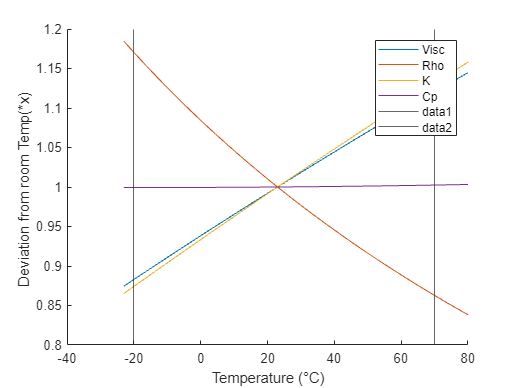


devKinVisc = v/BaselineKinVisc_T;
devRho = rho/BaselineRho;
devKcond = K/BaselineKcond;
devCpmass = Cp/BaselineCpmass;

figure;
hold on;
plot(T-273.15,devKinVisc,'DisplayName','Visc')
legend()
plot(T-273.15,devRho,"DisplayName","Rho")
plot(T-273.15,devKcond,"DisplayName","K")
plot(T-273.15,devCpmass,"DisplayName","Cp");
xline(-20)
xline(70)
xlabel("Temperature (°C)")
ylabel("Deviation from room Temp(*x) ")
hold off

Lets input an example to see how much this change in properties will have on the nusselt number. 

This represents cylinder in cross flow

%this code isn't the highest priority right now, the idea would be to have
%different cooilng enviroments to get different fluid properties
% I my plan is to use 